# Exercício 2

O .*pdf *acompanha um arquivo comprimido com os códigos mencionados.

- 1. Com algumas alterações no código usado para análise do exemplo 1, é possível analisar o sistema de segunda ordem do exemplo 2. Para que a análise do filtro seja feita apenas no item 3, na função MAIN este passo é comentado. As alterações principais são ilustradas a seguir:

**            Introdução do parâmetro v: **

                    Precisamos, pois o sistema é de segunda ordem.

**            Dividimos a integração em dois passos de Euler:**

                            
$$x(k+1) = x(k) + Tv(k)\\
v(k+1) = v(k) + T(u(k)+d(k))

$$


- 2. Com a função MAIN já alterada, fazemos esta ser agora uma chamada com *T *e *dmax* variando:

             a) *dmax *fixo e *T *variável:

Exemplo 1.2 com T = 0.1, dmax = 0.5


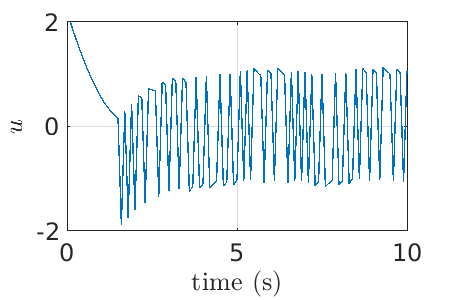

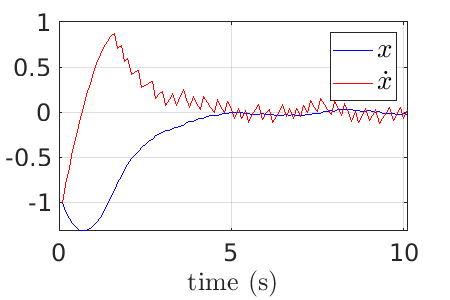

Exemplo 1.2 com T = 0.01, dmax = 0.5


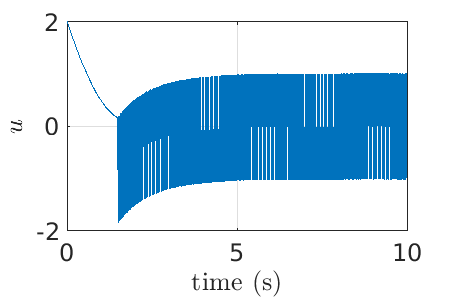

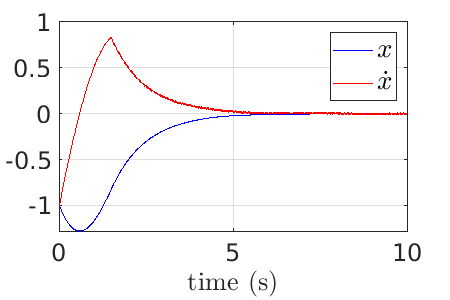

Exemplo 1.2 com T = 0.001, dmax = 0.5


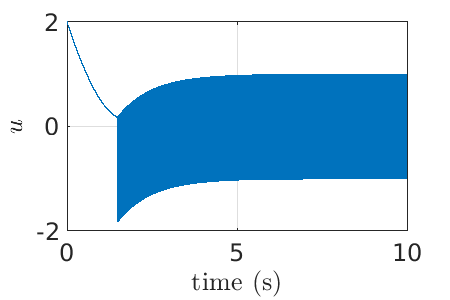

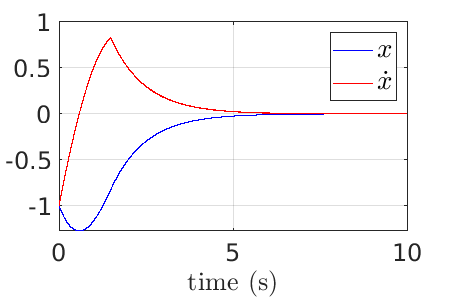

Exemplo 1.2 com T = 0.0001, dmax = 0.5


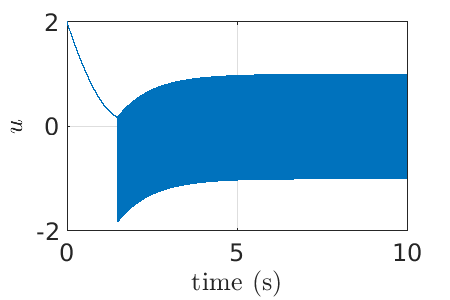

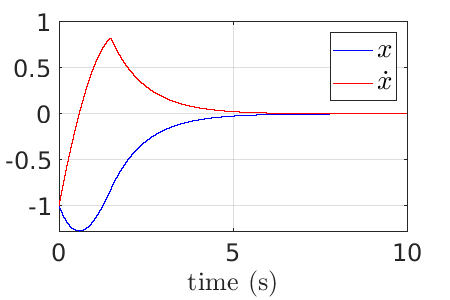

Exemplo 1.2 com T = 1e-05, dmax = 0.5


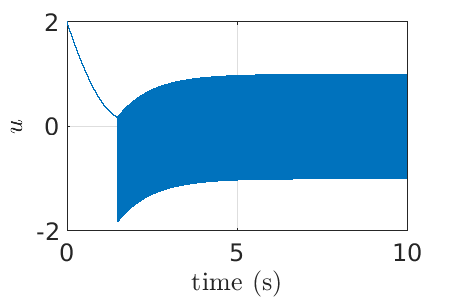

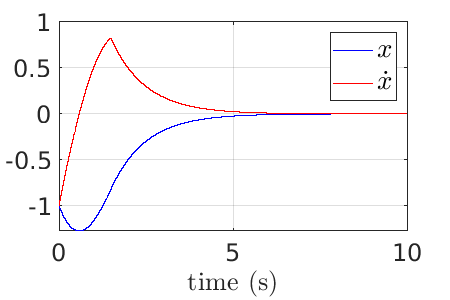

for i = 1:5
    T = (10^-1)^i;
    
    MAIN(T,0.5)
end

            Observa-se uma diferença considerável no resultado. Para $T=0\ldotp 1,0\ldotp 01,0\ldotp 001$, é visível as oscilações.

            Para $T=0\ldotp 0001$, porém, já fica clara a estabilidade na escala e intervalo de tempo considerados.

            b) *dmax *variável, *T *fixo

Exemplo 1.2 com T = 0.0001, dmax = 0.5


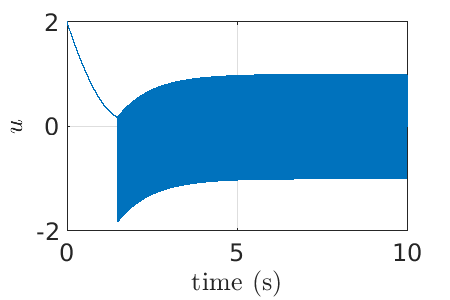

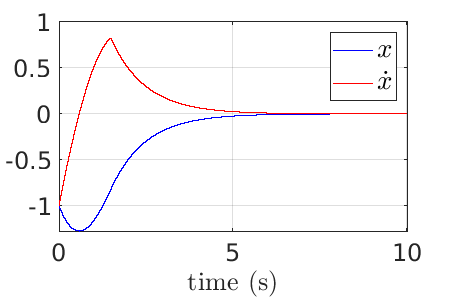

Exemplo 1.2 com T = 0.0001, dmax = 1


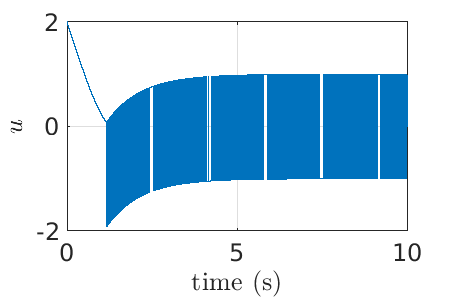

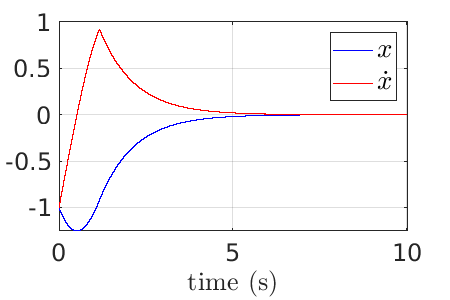

Exemplo 1.2 com T = 0.0001, dmax = 1.5


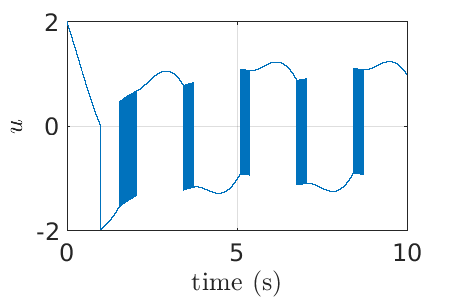

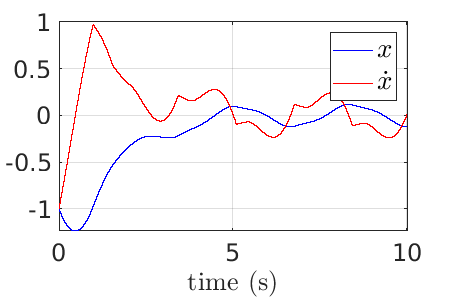

Exemplo 1.2 com T = 0.0001, dmax = 2


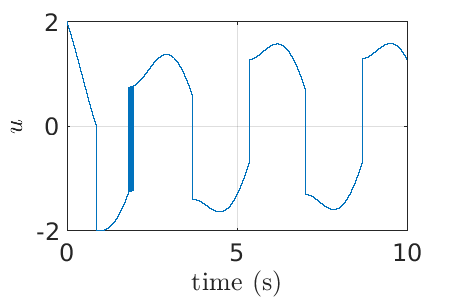

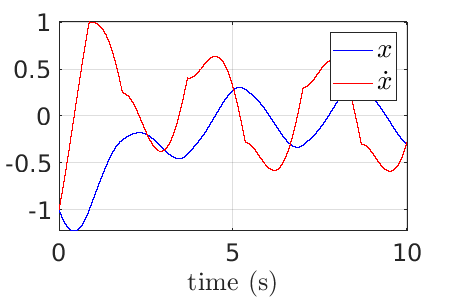

for i = 1:4
    MAIN(0.0001,0.5*i)
end

            Observa-se, neste item, como o sistema perde estabilidade com valores elevados do valor máximo do distúrbio.

            Embora não seja visível o efeito já com $L=1$, fica claro que não é garantido estado deslizante para valores superiores. 

- 3. Para a comparação, temos a MAIN_NO_FILTER, que tem como entrada a frequência de corte apenas.

Exemplo 1.2 com fc = 3
, T = 0.001, L = 0.5


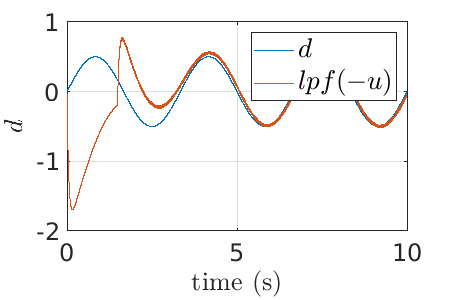

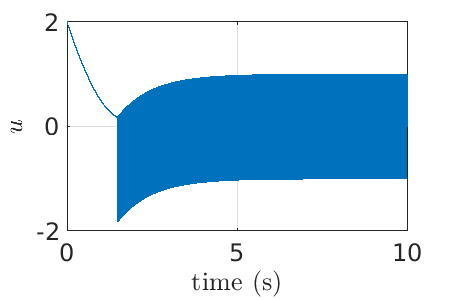

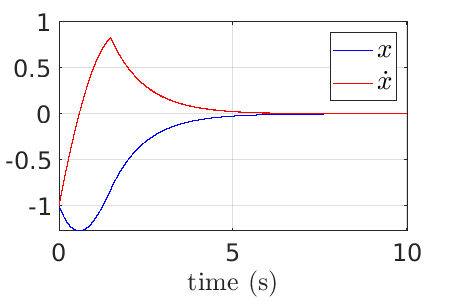

MAIN_NO_FILTER(3)

Exemplo 1.2 com fc = 1
, T = 0.001, L = 0.5


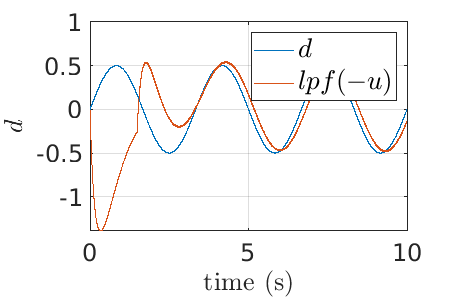

MAIN_NO_FILTER(1)

Exemplo 1.2 com fc = 9
, T = 0.001, L = 0.5


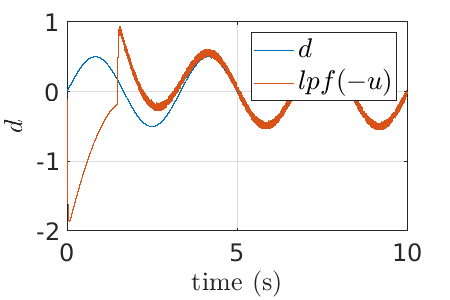

MAIN_NO_FILTER(9)

                    Observa-se que aumentar o valor da frequência de corte torna o sistema de predição mais instável, o que pode ser explicado pelo fato que são permitidas frequências cada vez mais altas. O sistema tem predição adiantada quando se diminui a frequência de corte, tornando a previsão do distúrbio mais rápida. Logicamente há um limite para o quanto se diminui a frequência de corte, ao passo que pode-se perder completamente o sinal do distúrbio com a atenuação do ganho numa frequência de interesse.